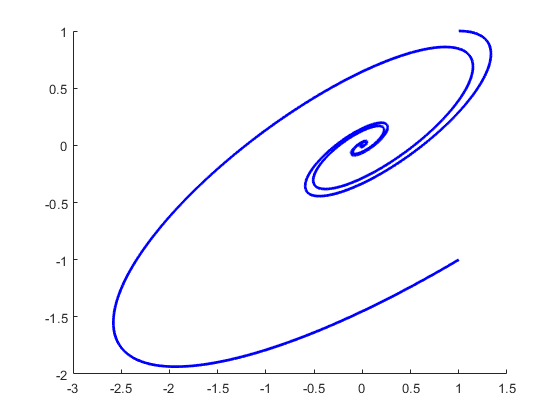

clear all 
format long

N = 10000;
dt = 0.01;

x= zeros(2,N+1);
y = zeros(2,N+1);

t = zeros(1,N+1);
x(1,1) = 1;
y(1,1) = 1;
x(2,1) = 1;
y(2,1) = -1;
t(1) = 0; 

for i = 1:2
for j = 1:N
    t(j+1) = t(j) +dt ;
    k1 = dt*eqf1(x(i,j),y(i,j));
    l1 = dt*eqf2(x(i,j),y(i,j));
    k2 = dt*eqf1(x(i,j)+ 0.5*k1,y(i,j)+0.5*l1);
    l2 = dt*eqf2(x(i,j)+0.5*k1,y(i,j)+0.5*l1);
    k3 = dt*eqf1(x(i,j)+ 0.5*k2,y(i,j)+0.5*l2);
    l3 = dt*eqf2(x(i,j)+0.5*k2,y(i,j)+0.5*l2);
    k4 = dt*eqf1(x(i,j)+k3,y(i,j)+l3);
    l4 = dt*eqf2(x(i,j)+k3,y(i,j)+l3);
    x(i,j+1) = x(i,j) + (k1+2*k2 +2*k3+k4)/6 ;
    y(i,j+1) = y(i,j) + (l1+2*l2 +2*l3+l4)/6 ;
end
end

hold on ;
plot(x(1,:),y(1,:),'-b','LineWidth',2);
plot(x(2,:),y(2,:),'-b','LineWidth',2);

axis([-1 1 ])



Next

clear all 
format long

N = 10000;
dt = 0.01;

x= zeros(3,N+1);
y = zeros(3,N+1);

t = zeros(1,N+1);
x(1,1) = 2;
y(1,1) = 2;
x(2,1) = 2;
y(2,1) = -0;
x(3,1) = 2;
y(3,1) = -2;
x(4,1) = 2;
y(4,1) = -2;
x(5,1) = 2;
y(5,1) = -2;
x(6,1) = 2;
y(6,1) = -2;
x(7,1) = 2;
y(7,1) = -2;
x(8,1) = 2;
y(8,1) = -2;
%square of lenght 4 make it

t(1) = 0; 

for i = 1:8
for j = 1:N
    t(j+1) = t(j) +dt ;
    k1 = dt*eqf1(x(i,j),y(i,j));
    l1 = dt*eqf2(x(i,j),y(i,j));
    k2 = dt*eqf1(x(i,j)+ 0.5*k1,y(i,j)+0.5*l1);
    l2 = dt*eqf2(x(i,j)+0.5*k1,y(i,j)+0.5*l1);
    k3 = dt*eqf1(x(i,j)+ 0.5*k2,y(i,j)+0.5*l2);
    l3 = dt*eqf2(x(i,j)+0.5*k2,y(i,j)+0.5*l2);
    k4 = dt*eqf1(x(i,j)+k3,y(i,j)+l3);
    l4 = dt*eqf2(x(i,j)+k3,y(i,j)+l3);
    x(i,j+1) = x(i,j) + (k1+2*k2 +2*k3+k4)/6 ;
    y(i,j+1) = y(i,j) + (l1+2*l2 +2*l3+l4)/6 ;
end
end

hold on ;
plot(x(1,:),y(1,:),'-b','LineWidth',2);
plot(x(2,:),y(2,:),'-b','LineWidth',2);
plot(x(3,:),y(3,:),'-b','LineWidth',2);